# First Order Ordinary Linear Systems : Sketch and Solve

% Sloution Benchmark
u  = @(x) [sin(x) ;  cos(x)] ;
Du = @(x) [cos(x) ; -sin(x)] ; 

% System Settings
m  = 2 ;  % number of dependent variables
A1 = @(x) [cos(x), -sin(x); sin(x), cos(x)];
A0 = @(x) [cos(x), -sin(x); sin(x), cos(x)];
f  = @(x) [1 ; 1]  ;
g  = @(x) sin(x) +  cos(x);  % u(x)
Omega = [ 0 , pi ] ;         % Omega = [ a , b ] domain

% Construct the model
h = [0.005, 0.0075, 0.01, 0.025, 0.05, 0.075, 0.1]; num_sample = length(h);
skt_coe = 4; rng(42); num_coworker = 10;
k = ceil(1./(pi*h)); k = arrayfun(@(x)max([x,10]),k); % k*（n-1） interior points for n basis
lambda = h.^(-3/2);
sample = cell(7, num_sample);

% load('./data/1DconvSample/1DconvSampleModel_stat.mat')
addpath('./Skechers/');

for j = 1:num_sample
    fprintf("Sample %d starts : ", j)

    % Construction
    model = Collocation1D(m, Omega);
    model.fitInterior(A1,A0,f,2);
    model.fitBoundary([],@(x) [1,1],g,1); 
    model.fitTrueSol(u, Du);
    
    % Discretization
    n = round(pi/h(j)) + 1;
    model.linear_discretize(n);
    interior_points = linspace(Omega(1), Omega(2), k(j)*(n-1) + n);

    % System assemble
    Lambda = lambda(j)*eye(1);
    [B_Omega, d_Omega, ~] = model.Assemble_B_Omega(interior_points);
    [B_Gamma, d_Gamma, ~] = model.Assemble_B_Gamma(Omega, Lambda);
    B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; [mB, nB] = size(B_Omega);
    mS = min([mB,skt_coe * nB]);

    % System solving without sketching and store data
    c = B\d; origin = struct();  
    model.C = model.reshape2mat(c);
    origin.L2 = model.Hk_error([], 0);
    origin.H1 = model.Hk_error([], 1);
    origin.res = norm(B*c-d);
    origin.sigmaB = svds(B, 1, 'smallest');
    origin.cond = svds(B,1)/origin.sigmaB;
    origin.ratio = round(mB/nB);
    sample{7,j} = origin;

    for i = 1:6
        fprintf("Sample %d starts : %d/6\n", j, i);
        sketcher = struct(); 

        switch i
            case 1
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Gaussian');
            case 2
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {1, 'Regular'});
            case 3
                s = ceil(log(nB));
                [SBd, ~] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {s, 'Regular'});
            case 4
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Gaussian');
            case 5
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {1, 'Regular'});
            case 6
                s = ceil(log(nB));
                [SBd, ~] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {s, 'Regular'});  
        end

        SBd = [SBd; [B_Gamma, d_Gamma]]; 
        SB = SBd(:,1:end-1); Sd = SBd(:,end);
        sketcher.sol = SB\Sd;
        Cskt = model.reshape2mat(sketcher.sol);
        sketcher.L2 = model.Hk_error(Cskt, 0);
        sketcher.H1 = model.Hk_error(Cskt, 1);
        sketcher.error = norm(sketcher.sol-reshape(model.C,[],1));
        sketcher.res = norm(B*sketcher.sol-d);
        sketcher.k = (sketcher.res ./ origin.res).^2;
        sketcher.epsilon = (sketcher.k-1)/(sketcher.k+1);
        sketcher.error_bound = (origin.res./origin.sigmaB) * (1+sqrt((1+sketcher.epsilon)/(1-sketcher.epsilon)));

        sketcher.sigmaB = svds(SB, 1, 'smallest');
        sketcher.cond = svds(SB,1)/sketcher.sigmaB;
        sample{i,j} = sketcher;
    end
    % save('./data/1DconvSample/1DconvSampleModel_stat.mat', 'sample');
end

load('./data/1DconvSample/1DconvSampleModel_stat.mat')
h = [0.005, 0.0075, 0.01, 0.025, 0.05, 0.075, 0.1];
color = [0.6350,  0.0780,  0.1840; 
         0.8500,  0.3250,  0.0980; 
         247/255, 152/255, 36/255; 
         30/255,  70/255,  110/255;
         45/255, 106/255, 79/255];

face_color = [238, 115, 125; 
              244, 169, 97; 
              255, 226, 84; 
              78,  127, 196;
              118, 200, 147]./255;

cellfun(@(x) x.ratio, sample(7,:))

ans =     65    44    33    14    11    11    11


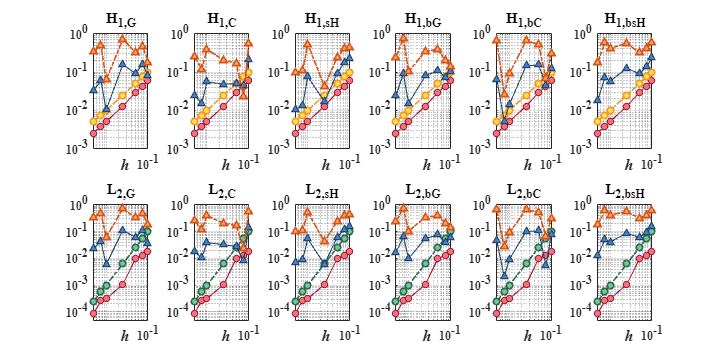

% Plot Error
H1 = cellfun(@(x) x.H1,sample(7,:));
L2 = cellfun(@(x) x.L2,sample(7,:));

figure; set(gcf,'position',[0, 0, 900, 450]); tiledlayout(2,6); 
Htitles = {'H_{1,G}', 'H_{1,C}', 'H_{1,sH}', 'H_{1,bG}', 'H_{1,bC}', 'H_{1,bsH}'};
Ltitles = {'L_{2,G}', 'L_{2,C}', 'L_{2,sH}', 'L_{2,bG}', 'L_{2,bC}', 'L_{2,bsH}'};

for i = 1:6
    nexttile(i);
    plotdata = cellfun(@(x) x.H1, sample(i,:));
    plotdata2 = cellfun(@(x) x.error, sample(i,:));

    loglog(h, H1, '-o', 'Color', color(1,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(1,:)); 
    hold on; grid on; box on;
    loglog(h, h,  '-.o', 'Color', color(3,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(3,:)); 
    loglog(h, plotdata, '-^', 'Color', color(4,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(4,:)); 
    loglog(h, plotdata2, '-.^', 'Color', color(2,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(2,:)); 

    xticks([0 0.1]); ylim([0.001 1]); 
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.00035;
    title(Htitles{i},'fontweight','bold','FontSize',14);
end

for i = 1:6
    nexttile(6+i);
    plotdata = cellfun(@(x) x.L2, sample(i,:));
    plotdata2 = cellfun(@(x) x.error, sample(i,:));

    loglog(h, L2, '-o', 'Color', color(1,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(1,:)); 
    hold on; grid on; box on;
    loglog(h, 10*h.^2,  '-.o', 'Color', color(5,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(5,:)); 
    loglog(h, plotdata, '-^', 'Color', color(4,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(4,:)); 
    loglog(h, plotdata2, '-.^', 'Color', color(2,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(2,:)); 

    xticks([0 0.1]);
    ylim([0.5e-4 1]); yticks([0.0001, 0.001, 0.01, 0.1, 1]);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.000018;
    title(Ltitles{i},'fontweight','bold','FontSize',14);
end

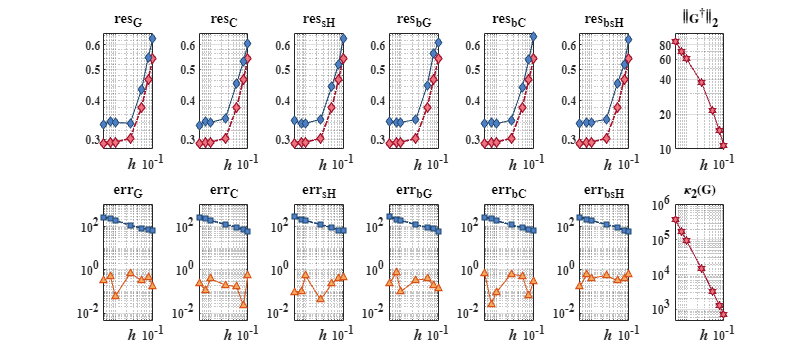

% Plot Skt Error
res = cellfun(@(x) x.res,sample(7,:));
sigB = cellfun(@(x) x.sigmaB, sample(7,:));
cond = cellfun(@(x) x.cond, sample(7,:));
figure; set(gcf,'position',[0, 0, 1000, 450]); tiledlayout(2,7); 
restitles = {'res_{G}', 'res_{C}', 'res_{sH}', 'res_{bG}', 'res_{bC}', 'res_{bsH}'};
errtitles = {'err_{G}', 'err_{C}', 'err_{sH}', 'err_{bG}', 'err_{bC}', 'err_{bsH}'};

for i = 1:6
    nexttile(i);
    plotdata = cellfun(@(x) x.res, sample(i,:));
    loglog(h, res, '-.diamond', 'Color', color(1,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(1,:)); 
    hold on; grid on; box on;
    loglog(h, plotdata, '-diamond', 'Color', color(4,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(4,:)); 

    xticks([0 0.1]); ylim([0.28, 0.65]); 
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.026;
    title(restitles{i},'fontweight','bold','FontSize',14);
end

for i = 1:6
    nexttile(7+i);

    plotdata = cellfun(@(x) x.error, sample(i,:));
    plotdata2 = cellfun(@(x) x.error_bound, sample(i,:));

    loglog(h, plotdata, '-^', 'Color', color(2,:), 'LineWidth', 1, 'MarkerFaceColor', face_color(2,:));
    hold on; grid on; box on;
    loglog(h, plotdata2, '-.square', 'Color', color(4,:), 'LineWidth', 1.5, 'MarkerFaceColor', face_color(4,:)); 

    xticks([0 0.1]);
    ylim([0.5e-2 1e3]); yticks([0.0001,  0.01,  1,  100]);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
    xh.Position(2) = xh.Position(2) + 0.002;
    title(errtitles{i},'fontweight','bold','FontSize',14);
end

nexttile(7);
loglog(h, 1./sigB, '-hexagram', 'Color', color(1,:), 'LineWidth', 1, 'MarkerSize', 7, 'MarkerFaceColor', face_color(1,:)); 
grid on; box on; xticks([0 0.1]);
ylim([10, 100]); yticks([10, 20, 40, 60, 80]);
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
th = title('$\mathbf{\left \|  G^{\dagger}\right \|_2}$','Interpreter','latex');
xh.Position(2) = xh.Position(2) + 2.45;
% th.Position(2) = th.Position(2) - 8;

nexttile(14);
loglog(h, cond, '-hexagram', 'Color', color(1,:), 'LineWidth', 1, 'MarkerSize', 7, 'MarkerFaceColor', face_color(1,:)); 
grid on; box on; xticks([0 0.1]); 
ylim([5e2, 1e6]); yticks([0.1,1,10,100]*1e4); 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
xh = xlabel("\it h",'FontSize', 15, 'FontWeight', 'bold');
xh.Position(2) = xh.Position(2) + 210;
title('$\mathbf{\kappa_2(G)}$','Interpreter','latex');